% Load the Brain Connectivity Toolbox (ensure it is in your MATLAB path)

% Step 1: Load the ROI labels from the provided file
roi_labels = importdata('labels.txt'); % Load the ROI labels file
rois = roi_labels; % Assume the file lists the ROIs line by line

% Step 2: Load the connectivity matrices for controls and patients
n_patients = 11; % Number of patients
n_controls = 11; % Number of controls (participants 12 to 22)

total_participants = n_patients + n_controls;
patients = cell(n_patients, 1);
controls = cell(n_controls, 1);

for i = 1:n_patients
    patients{i} = readmatrix([num2str(i) '_thresholded.txt']); % Load patient connectivity matrix
end

for i = 1:n_controls
    controls{i} = readmatrix([num2str(i + n_patients) '_thresholded.txt']); % Load control connectivity matrix
end

% Step 3: Identify ROI indices for analysis
roi_indices = 1:length(rois); % Use all ROIs from the file

% Step 4: Compute Metrics for Controls and Patients
node_degree_controls = zeros(n_controls, length(roi_indices));  
node_degree_patients = zeros(n_patients, length(roi_indices));

local_efficiency_controls = zeros(n_controls, length(roi_indices));
local_efficiency_patients = zeros(n_patients, length(roi_indices));

betweenness_controls = zeros(n_controls, length(roi_indices));
betweenness_patients = zeros(n_patients, length(roi_indices));

global_efficiency_controls = zeros(n_controls, 1);
global_efficiency_patients = zeros(n_patients, 1);

edge_strength_controls = cell(n_controls, 1);
edge_strength_patients = cell(n_patients, 1);

edge_betweenness_controls = cell(n_controls, 1);
edge_betweenness_patients = cell(n_patients, 1);

for i = 1:n_controls
    control_matrix = controls{i};
    roi_control_matrix = control_matrix(roi_indices, roi_indices);
    node_degree_controls(i, :) = degrees_und(roi_control_matrix);
    local_efficiency_controls(i, :) = efficiency_wei(roi_control_matrix, 1);
    betweenness_controls(i, :) = betweenness_wei(roi_control_matrix);
    global_efficiency_controls(i) = efficiency_wei(roi_control_matrix, 0);
    edge_strength_controls{i} = roi_control_matrix;
    edge_betweenness_controls{i} = edge_betweenness_bin(roi_control_matrix);
end

for i = 1:n_patients
    patient_matrix = patients{i};
    roi_patient_matrix = patient_matrix(roi_indices, roi_indices);
    node_degree_patients(i, :) = degrees_und(roi_patient_matrix);
    local_efficiency_patients(i, :) = efficiency_wei(roi_patient_matrix, 1);
    betweenness_patients(i, :) = betweenness_wei(roi_patient_matrix);
    global_efficiency_patients(i) = efficiency_wei(roi_patient_matrix, 0);
    edge_strength_patients{i} = roi_patient_matrix;
    edge_betweenness_patients{i} = edge_betweenness_bin(roi_patient_matrix);
end

% Step 5: Compute Average Edge Metrics
avg_edge_strength_controls = mean(cat(3, edge_strength_controls{:}), 3);
avg_edge_strength_patients = mean(cat(3, edge_strength_patients{:}), 3);

avg_edge_betweenness_controls = mean(cat(3, edge_betweenness_controls{:}), 3);
avg_edge_betweenness_patients = mean(cat(3, edge_betweenness_patients{:}), 3);

% Step 6: Identify Significant Edges
edge_p_values = zeros(length(roi_indices), length(roi_indices));
for i = 1:length(roi_indices)
    for j = 1:length(roi_indices)
        edge_values_controls = cellfun(@(x) x(i, j), edge_strength_controls);
        edge_values_patients = cellfun(@(x) x(i, j), edge_strength_patients);
        edge_p_values(i, j) = ranksum(edge_values_controls, edge_values_patients);
    end
end

edge_p_fdr = mafdr(edge_p_values(:), 'BHFDR', true);
edge_p_fdr = reshape(edge_p_fdr, size(edge_p_values));

% Step 7: Display Edge Metrics and Significant Differences
fprintf('Edge Strength (Mean ± SD):\n');

Edge Strength (Mean ± SD):


fprintf('Controls: %.3f ± %.3f\n', mean(avg_edge_strength_controls(:)), std(avg_edge_strength_controls(:)));

Controls: 0.033 ± 0.050


fprintf('Patients: %.3f ± %.3f\n', mean(avg_edge_strength_patients(:)), std(avg_edge_strength_patients(:)));

Patients: 0.038 ± 0.055



fprintf('\nEdge Betweenness (Mean ± SD):\n');


Edge Betweenness (Mean ± SD):


fprintf('Controls: %.3f ± %.3f\n', mean(avg_edge_betweenness_controls(:)), std(avg_edge_betweenness_controls(:)));

Controls: 1.486 ± 1.761


fprintf('Patients: %.3f ± %.3f\n', mean(avg_edge_betweenness_patients(:)), std(avg_edge_betweenness_patients(:)));

Patients: 1.360 ± 1.408



fprintf('\nSignificant Edges (FDR-adjusted p-values < 0.05):\n');


Significant Edges (FDR-adjusted p-values < 0.05):


for i = 1:length(roi_indices)
    for j = 1:length(roi_indices)
        if edge_p_fdr(i, j) < 0.05
            fprintf('Edge %s-%s: p = %.4f\n', rois{i}, rois{j}, edge_p_fdr(i, j));
        end
    end
end

Edge Sensory Cortex Right-Thalamus Right: p = 0.0089
Edge Thalamus Right-Sensory Cortex Right: p = 0.0089


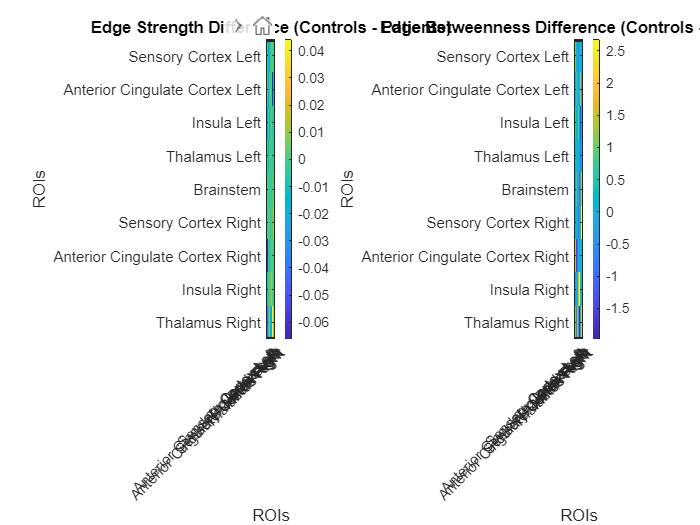


% Step 8: Visualize Edge Strength and Betweenness
figure;
subplot(1, 2, 1);
imagesc(avg_edge_strength_controls - avg_edge_strength_patients);
colorbar;
title('Edge Strength Difference (Controls - Patients)');
xlabel('ROIs'); ylabel('ROIs');
xticks(1:length(roi_indices)); xticklabels(rois);
yticks(1:length(roi_indices)); yticklabels(rois);
xtickangle(45);

subplot(1, 2, 2);
imagesc(avg_edge_betweenness_controls - avg_edge_betweenness_patients);
colorbar;
title('Edge Betweenness Difference (Controls - Patients)');
xlabel('ROIs'); ylabel('ROIs');
xticks(1:length(roi_indices)); xticklabels(rois);
yticks(1:length(roi_indices)); yticklabels(rois);
xtickangle(45);